clear;
A = [0 1; 0 0];
B = [0; 1];
Bw = [1 0; -1 0];
x0 = [0; 0];
w0 = [0; 0];
C = [1 0];
Dw = [0 1];

Cz1 = [-1 2; 0 0];
Dz1 = [0; 1];


Cz2 = [0 0; -2 1];
Dz2 = [1; 0];

%=====Checkers=====
a1 = det(Dz1'*Dz1);
a2 = det(Dz2'*Dz2);
a3 = det(Dw*Dw');
ans_1 = Cz1'*Dz1;
ans_2 = Cz2'*Dz2;
ans_3 = Bw*Dw';
U = [B A*B];
du1 = rank(U);
U2 = [Bw A*Bw];
du2 = rank(U2);
V = [C; C*A];
dv = rank(V);
V1 = [Cz1; Cz1*A];
dv1 = rank(V1);
V2 = [Cz2; Cz2*A];
dv2 = rank(V2);



C_Z = Cz2;
D_Z = Dz2;

det(C_Z'*C_Z)

ans = 0

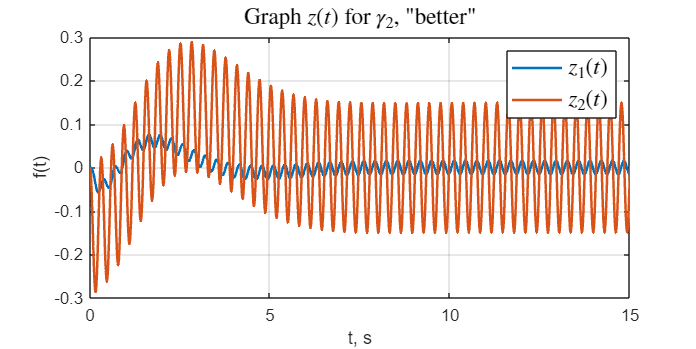


%========== Task 3-4 ========================

g_1 = 5;
g_2 = 15;
g_ = g_2;
%{
[Q, K] = ric_inf_reg(A, B, C_Z, D_Z, Bw, g_)
eig(Q)
eig(A+B*K)
%s = tf('s');
%syms s;
sys = ss(A+B*K, Bw, C_Z+D_Z*K, zeros(2, 2));
TF = tf(sys)
syms s;
W_matrix = [TF(1,1) TF(1,2); TF(2,1) TF(2,2)]
%}
[PL, L, X, K] = ric_inf_obs(A, B, C, C_Z, D_Z, Bw, Dw, g_);
eig(X);
eig(PL);

%=====Simulation=========

open_system('task_2_sim');
set_param('task_2_sim/z', 'VariableName', 'z')
out = sim('task_2_sim');

figure('Position', [100 100 800 400])
plot(out.z,'-', 'LineWidth',1.5);

grid()
title('Graph $z(t)$ for $\gamma_2$,  "better"','Interpreter','latex',  'FontSize', 14)
legend('$z_1(t)$', '$z_2(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off



%===========Tasks 1 & 2 ============================
%{
% Вычисляем необходимые компоненты
R = D_Z' * D_Z;
Q_riccati = C_Z' * C_Z;

% Решаем уравнение Риккати
[Q,~,K] = icare(A, B, Q_riccati, R, [], [], [], 1);

% Выводим решение
disp('Решение Q:');
disp(Q);

K = -pinv(D_Z' * D_Z)*B'*Q;
disp('Решение K:');
disp(K);
disp(eig(A+B*K));

% Находим наблюдатель
Qr = Bw*Bw';
Rr = Dw*Dw';
[P1,~,~] = icare(A', C', Qr, Rr, [], [], [], 1);  
P1
L = -P1* C' * inv(Rr)

%=====Передаточная функция====
%syms s;
%W_wzL = simplify([C_Z+D_Z*K -D_Z*K]*inv(s*eye(4) - [A+B*K -B*K; zeros(2) A-L*C])*[Bw;Bw-L*Dw])
%sys = ss([A B*K; -L*C A+B*K+L*C], [Bw; Bw-L*Dw], [C_Z D_Z*K], zeros(2, 2))
%TF = tf(sys)


% Передаточная функция

sys = ss([A, B*K;-L*C, A+B*K+L*C], [Bw; -L*Dw], [C_Z, D_Z*K], zeros(2, 2));
TF = tf(sys)
syms s;
W_matrix = [TF(1,1) TF(1,2); TF(2,1) TF(2,2)];


H2_norm = norm(W_matrix, 2)
%trace(C_Z*P1*C_Z')^0.5
Hinf_norm = norm(sys, inf)

omega = linspace(0, 2, 5000); 
[H, ~] = freqresp(W_matrix, omega);

sigma_values = zeros(2, length(omega)); % Для 2x2 системы (2 сингулярных числа на каждой частоте)
for k = 1:length(omega)
    s = 1i * omega(k); % s = j*omega
    W_freq = evalfr(W_matrix, s); % Вычисление W(j*omega)
    sigma_values(:, k) = svd(W_freq); % Сингулярные числа
end

figure('Position', [100 100 800 400]);
plot(omega, sigma_values(1,:), '-', 'LineWidth',2);
hold on
plot(omega, sigma_values(2,:), ':', 'LineWidth',2);
grid()
title('Graph $\sigma (\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$\sigma_{1}(\omega)$', '$\sigma_{2}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('$\sigma (abs)$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off


figure('Position', [100 100 800 400]);
plot(omega, squeeze(abs(H(1,1,:))), '-', 'LineWidth',2);
hold on
plot(omega, squeeze(abs(H(1,2,:))), '--', 'LineWidth',2);
plot(omega, squeeze(abs(H(2,1,:))), '-.', 'LineWidth',2);
plot(omega, squeeze(abs(H(2,2,:))), ':', 'LineWidth',2);

grid()
title('Graph $A(\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$A_{11}(\omega)$', '$A_{12}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('$|A|$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off
%}

%{
s = tf('s');

%W_wz = simplify((C_Z + D_Z*K)*inv(s*eye(2)-A-B*K)*Bw)
%W_wz = (C_Z + D_Z*K)*inv(s*eye(2)-A-B*K)*Bw;
H2_norm = norm(W_wz, 2)
trace(Bw'*Q*Bw)^0.5
Hinf_norm = norm(W_wz, inf)

w_s = 0:0.001:10;
s_1 = sigma(W_wz, w_s);
figure('Position', [100 100 800 400]);
plot(w_s, s_1, '-', 'LineWidth',2);
grid()
title('Graph $\sigma (\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$\sigma_{1}(\omega)$', '$\sigma_{2}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('$\sigma (abs)$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')


s = tf('s');

%W_wz = simplify((C_Z + D_Z*K)*inv(s*eye(2)-A-B*K)*Bw)
W_wz = (C_Z + D_Z*K)*inv(s*eye(2)-A-B*K)*Bw
syms w real;

ww11 = subs(W_wz(1,1), s, 1j*w) 
ww12 = subs(W_wz(1,2), s, 1j*w)
ww21 = subs(W_wz(2,1), s, 1j*w)
ww22 = subs(W_wz(2,2), s, 1j*w)

P1 = [real(ww11) real(ww12); real(ww21) real(ww22)]
Q1 = [imag(ww11) imag(ww12); imag(ww21) imag(ww22)]
Afc1 = simplify(sqrt(P1.*P1 + Q1.*Q1))
w_x = 0:0.001:10;

Afc11 = double(subs(Afc1(1,1), w, w_x));
Afc12 = double(subs(Afc1(1,2), w, w_x));
Afc13 = double(subs(Afc1(2,1), w, w_x));
Afc14 = double(subs(Afc1(2,2), w, w_x));

figure('Position', [100 100 800 400]);
plot(w_x, Afc11, '-', 'LineWidth',2);
hold on
plot(w_x, Afc12, '--', 'LineWidth',2);
plot(w_x, Afc13, '-.', 'LineWidth',2);
plot(w_x, Afc14, ':', 'LineWidth',2);

grid()
title('Graph $A(\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$A_{11}(\omega)$', '$A_{12}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('$|A|$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off

%}

function [X,K] = ric_inf_reg(A, B, CZ, DZ, Bw, g)
    Q = CZ'*CZ;
    R = DZ'*DZ;
    G = g^(-2)*Bw*Bw';
    [X,~,~] = icare(A, B, Q, R, [], [], G);
    if isempty(X)
        error('Решение уравнения Риккати не найдено.');
    end
    K = -inv(R)*B'*X;
end

function [PL, L, X, K] = ric_inf_obs(A, B, C, CZ, DZ, Bw, Dw, g)
    [X, K] =ric_inf_reg(A, B, CZ, DZ, Bw, g);
    Q = Bw*Bw';
    R = Dw*Dw';
    G = g^(-2)*(CZ')*CZ;
    [PL,~,~] = icare(A', C', Q, R, [], [], G);
    if isempty(PL)
        error('Решение уравнения Риккати не найдено.');
    end
     if max(eig(PL*X)) >= g^2
        error('Условие согласованности не выполнено.');
    end
    L = -PL*pinv(eye(2)-g^(-2)*X*PL)*((C+g^(-2)*Dw*Bw'*X)')*(R)^(-1);
end